clear

#### Read MFD data

[B0,freqs1,defects] = readMFD('data/B_defectless.txt');
assert(isempty(defects))

[B ,freqs2,defects] = readMFD('data/B_defect_circ8mm.txt');
assert(all(freqs1==freqs2))

freqs = freqs1;
delta_B = B - B0;

% currently use only one frequency
freqs = freqs(3);
delta_B = delta_B(3,:).';

clear freqs1 freqs2 B0 B

#### Load sensitivity matrix

load(sprintf('data/Sensitivity_%dHz.mat', freqs))

global xylim
xylim = 20e-3;
mask = -xylim < element_centers(1,:) &  element_centers(1,:) < xylim & ...
       -xylim < element_centers(2,:) &  element_centers(2,:) < xylim;

S = S(:, mask);
element_centers = element_centers(:, mask);

clear xylim mask 

#### Tikhonov regularization


$$\Delta \tilde{\sigma} =\textrm{argmin}\left\lbrace {\left\|S\Delta \sigma -\Delta B\right\|}_2^2 +\lambda {\left\|\Delta \sigma \right\|}_2^2 \right\rbrace$$


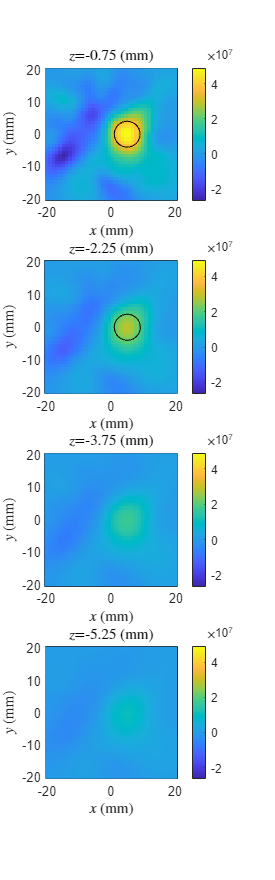

lambda = 1e-27;
R = (S' * S + lambda * eye(size(S,2))) \ S';

delta_sigma = R * delta_B;

displayReconstruction(delta_sigma, element_centers, defects)


clear lambda R delta_sigma

#### Sparsity regularization


$$\Delta \tilde{\sigma} =\textrm{argmin}\left\lbrace {\left\|S\Delta \sigma -\Delta B\right\|}_2^2 +\lambda {\left\|\Delta \sigma \right\|}_1 \right\rbrace$$


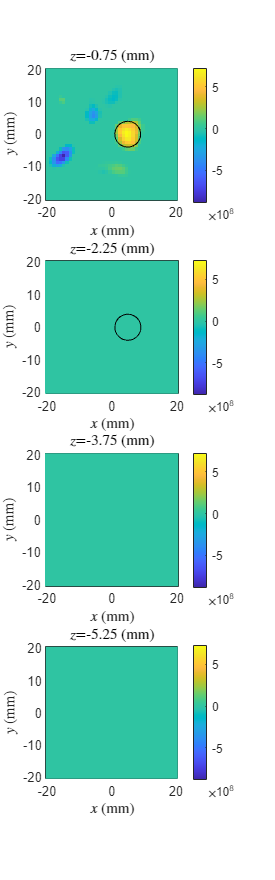

lambda = 1e-20;
beta = 1e-27;

R = decomposition(S' * S + beta * speye(size(S,2)));
delta_sigma = zeros(size(S,2), 1);
d = zeros(size(S,2), 1);
b = zeros(size(S,2), 1);

for i = 1:100
    delta_sigma = R \ (S' * delta_B + beta * (d - b));
    d = sthresh(delta_sigma + b, lambda/beta);
    b = b + (delta_sigma - d);
end

displayReconstruction(delta_sigma, element_centers, defects)


clear lambda beta i R d b delta_sigma

#### Total variation regularization


$$\Delta \tilde{\sigma} =\textrm{argmin}\left\lbrace {\left\|S\Delta \sigma -\Delta B\right\|}_2^2 +\lambda {\left\|L_x \Delta \sigma \right\|}_1 +\lambda {\left\|L_y \Delta \sigma \right\|}_1 \right\rbrace$$


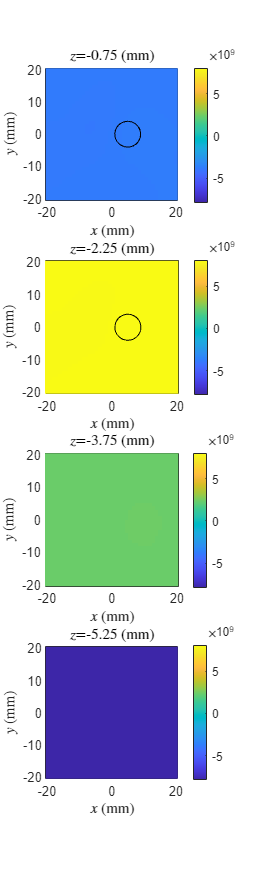

lambda = 1e-5;
beta = 1e-35;

[Lx,Ly,~] = grad_operator(element_centers);

R = decomposition(S' * S + beta * (Lx' * Lx) + beta * (Ly' * Ly));
delta_sigma = zeros(size(S,2), 1);
dx = zeros(size(S,2), 1);
bx = zeros(size(S,2), 1);
dy = zeros(size(S,2), 1);
by = zeros(size(S,2), 1);

for i = 1:100
    delta_sigma = R \ (S' * delta_B + beta * Lx' * (dx - bx) + beta * Ly' * (dy - by));
    dx = sthresh(Lx * delta_sigma + bx, lambda/beta);
    dy = sthresh(Ly * delta_sigma + by, lambda/beta);
    bx = bx + (Lx * delta_sigma - dx);
    by = by + (Ly * delta_sigma - dy);
end

displayReconstruction(delta_sigma, element_centers, defects)


clear lambda beta i Lx Ly R dx dy bx by delta_sigma

function x = sthresh(x, gamma)
xs = abs(x) - gamma;
xs(xs < 0) = 0;
x = xs .* sign(x);
end

function [Lx,Ly,Lz] = grad_operator(element_centers)

n = size(element_centers,2);
nx = length(unique(element_centers(1,:)));
ny = length(unique(element_centers(2,:)));
nz = length(unique(element_centers(3,:)));

x   = reshape(element_centers(1,:), nx,ny,nz);
y   = reshape(element_centers(2,:), nx,ny,nz);
z   = reshape(element_centers(3,:), nx,ny,nz);
idx = reshape(1:n, nx,ny,nz);

assert(all(x == x(:,1,1), 'all')); x = x(:,1,1); assert(issorted(x));
assert(all(y == y(1,:,1), 'all')); y = y(1,:,1); assert(issorted(y));
assert(all(z == z(1,1,:), 'all')); z = z(1,1,:); assert(issorted(z));

Lx = sparse(n,n);
Ly = sparse(n,n);
Lz = sparse(n,n);

for i = 1:nx
for j = 1:ny
for k = 1:nz
    idx_0 = idx(i,j,k);

    if i < nx
        idx_x = idx(i+1,j,k);
        dx = x(i+1) - x(i);
        Lx(idx_0, idx_0) =  1/dx;
        Lx(idx_0, idx_x) = -1/dx;
    end
    if j < ny
        idx_y = idx(i,j+1,k);
        dy = y(j+1) - y(j);
        Ly(idx_0, idx_0) =  1/dy;
        Ly(idx_0, idx_y) = -1/dy;
    end
    if k < nz
        idx_z = idx(i,j,k+1);
        dz = z(k+1) - z(k);
        Lz(idx_0, idx_0) =  1/dz;
        Lz(idx_0, idx_z) = -1/dz;
    end
end
end
end

end

function [B, freqs, defects] = readMFD(fname)

B = [];
freqs = [];
defects = {};

lines = readlines(fname);

for k = 1:length(lines)
    str = strtrim(lines(k));
    str = convertStringsToChars(str);
    if isempty(str)
        continue
    end

    if ~startsWith(str, '%')
        B(end+1,:) = str2num(str);
    else
        str = strtrim(str(2:end));
        if startsWith(str, 'frequency')
            tokens = split(str);
            freqs(end+1) = str2num(tokens{2});
            assert(strcmp(tokens{3}, "Hz"))
        elseif startsWith(str, 'defect')
            i = strfind(str, ' ');
            defects{end+1} = jsondecode(str(i:end));
        else
            error('Unknown "%s"', str)
        end
    end
end

end

function displayReconstruction(delta_sigma, element_centers, defects)

c = real(-delta_sigma);

z = unique(element_centers(3,:));
z = sort(z, 'descend');

scale = 1e3;

global xylim
lim = [-xylim xylim] * scale;

figure('Position',[10 10 400 300*length(z)])
for k = 1:length(z)
    mask = element_centers(3,:) == z(k);
    c_layer = reshape(c(mask), sqrt(sum(mask)),[]);

    subplot(length(z),1,k)
    hold on
    imagesc(lim,lim, c_layer.', [min(c) max(c)])
    colorbar
    axis square xy
    box on
    xlim(lim)
    ylim(lim)
    title(sprintf('$z$=%g (mm)',z(k)*scale), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')

    for p = 1:length(defects)
        defect = defects{p};
        if ~(min(defect.z1, defect.z2) <= z(k) && z(k) <= max(defect.z1, defect.z2))
            continue
        end
        switch lower(defect.type)
            case 'rectangular'
                rect = [defect.c_x-defect.dx/2 defect.c_y-defect.dy/2 defect.dx defect.dy];
                rectangle('Position', rect * scale)
            case 'circular'
                theta = linspace(0, 2*pi);
                x = defect.c_x + defect.d/2 * cos(theta);
                y = defect.c_y + defect.d/2 * sin(theta);
                plot(x * scale, y * scale, 'k')
            case 'polygonal'
                plot(defect.xs * scale, defect.ys * scale, 'k')
            otherwise
                error('Unknown defect shape "%s"', defect.type)
        end
    end
end

end